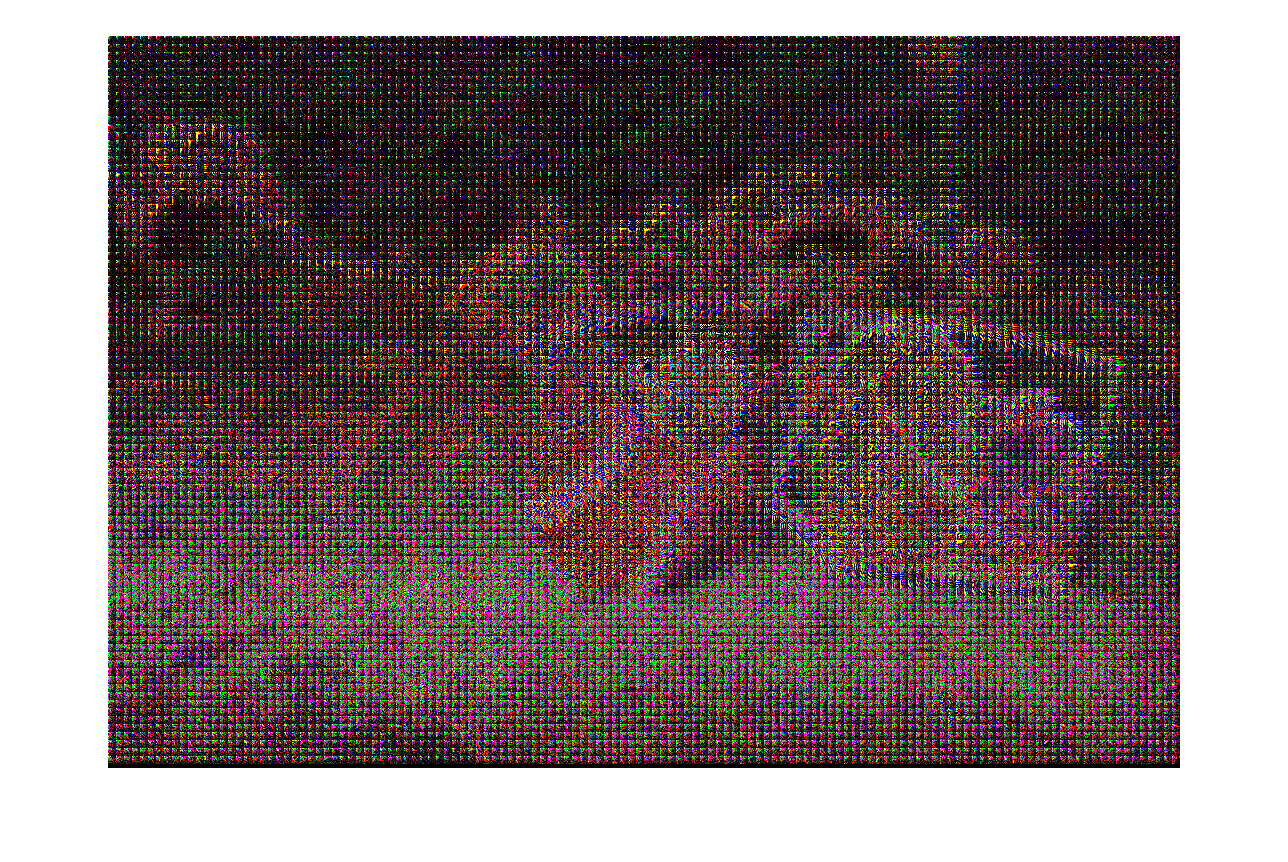

%convert the image to YUV type
[pilot] = imread('pilot.jpg');
[key] = imread('baseball.jpg');

key = imresize(key,[row,col]);

%YUV should be value in [0,255]
pilot_YUV=rgb2ycbcr(pilot);
key_YUV = rgb2ycbcr(key);

[row,col,channel]=size(pilot_YUV);
pilot_dct=zeros(row,col,channel);
pilot_qua=zeros(row,col,channel);
pilot_encode=zeros(row,col,channel);
key_dct=zeros(row,col,channel);
RLencode={[],[],[]};
DC_matrix={[],[],[]};

quatization_matrix=[
[16,11,10,16,24,40,51,61]
[12,12,14,19,26,58,60,55]
[14,13,16,24,40,57,69,56]
[14,17,22,29,51,87,80,62]
[18,22,37,56,68,109,103,77]
[24,35,55,64,81,104,113,92]
[49,64,78,87,103,121,120,101]
[72,92,95,98,112,100,103,99]];

%y=encode(quatization_matrix)
% slice each part into 8*8 matrix, do dct,quantization,encode
for i=1:row/8
    for j=1:col/8
        for k=1:channel
            downsample_pilot=pilot_YUV(8*i-7:8*i,8*j-7:8*j,k);
            downsample_key = key_YUV(8*i-7:8*i,8*j-7:8*j,k);
            % for each 8*8 input matrix apply dct
            key_dct(8*i-7:8*i,8*j-7:8*j,k) = dct2(downsample_key);
            pilot_dct(8*i-7:8*i,8*j-7:8*j,k)=dct2(downsample_pilot)*0.5+key_dct(8*i-7:8*i,8*j-7:8*j,k)*0.5;
            %divide by quantization matrix
            pilot_qua(8*i-7:8*i,8*j-7:8*j,k)=round(pilot_dct(8*i-7:8*i,8*j-7:8*j,k)./quatization_matrix);
            %zigzag & Run length encode
            [DC,pilot_encode(8*i-7:8*i,8*j-7:8*j,k),code]=encode(pilot_qua(8*i-7:8*i,8*j-7:8*j,k));
            % for each channel, run length encode link into a vector, store each DC term in another array 
            DC_matrix{k}=[DC_matrix{k},DC];
            RLencode{k}=[RLencode{k},code];
        end
    end
end

imshow(pilot_dct);


%pilot_YUV(567:578,567:578,:);
%pilot_dct(1:8,1:8,:);

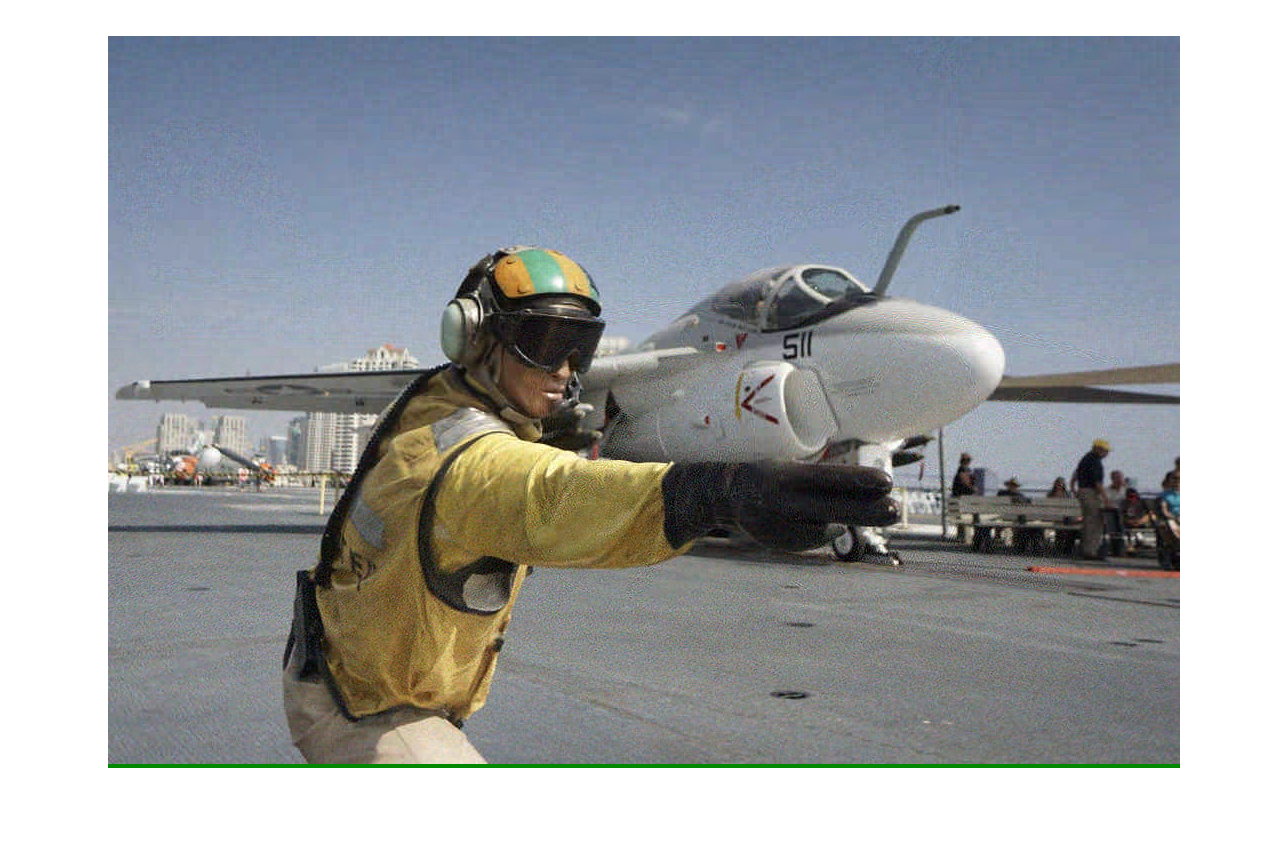

DC_cell = [];
AC_cell = [];
recover_decode = zeros(row,col,channel);
recover_quantization = zeros(row,col,channel);
recover_dct = zeros(row,col,channel);

for k=1:channel
    DC_cell = DC_matrix{k};
    AC_cell = RLencode{k};
    for i=1:row/8
        for j = 1:col/8
            if ~isempty(DC_cell) && ~isempty(AC_cell)
                [AC,AC_cell] = crop_AC (AC_cell);
                decode_temp = decode(DC_cell(1),AC);
                DC_cell(1)=[];
                recover_decode(8*i-7:8*i,8*j-7:8*j,k) = decode_temp;
                decode_temp = decode_temp .* quatization_matrix;
                recover_quantization(8*i-7:8*i,8*j-7:8*j,k)=decode_temp;
                % This step recover the effect of key
                decode_temp = (decode_temp - 0.5*key_dct(8*i-7:8*i,8*j-7:8*j,k))*2;
                
                recover_dct(8*i-7:8*i,8*j-7:8*j,k) = idct2(decode_temp);
            end
        end
    end
end

recover_dct = uint8(recover_dct);
recover_pilot=ycbcr2rgb(recover_dct);

imshow(recover_pilot);

recover_pilot(1:8,1:8,:);

ans = 8×8×3 uint8 array
ans(:,:,1) =

   91   91   91   91   93   93   94   94
   92   92   91   92   92   93   92   92
   92   92   91   92   90   92   91   90
   90   89   89   90   90   91   91   92
   90   90   88   88   91   92   92   93
   93   92   91   91   92   93   94   93
   96   96   94   95   93   93   93   92
   98   97   97   96   96   95   95   93


ans(:,:,2) =

   105   105   105   105   107   107   108   108
   106   106   104   105   105   107   107   107
   105   105   104   105   106   107   109   108
   108   107   107   108   107   109   109   110
   110   110   109   109   109   110   109   111
   114   113   111   111   110   111   109   107
   112   112   110   111   111   111   111   109
   111   110   110   109   112   112   112   113


ans(:,:,3) =

   132   132   132   132   136   136   137   137
   133   133   134   135   135   136   138   138
   135   135   134   135   137   138   139   138
   138   137   137   138   140   141   141   143
   139   139  